% Author: Kenneth H.L. Ho
% Copyright 2019 RIKEN BDR
% License: GPL v3 https://www.gnu.org/licenses/gpl-3.0.txt 

## Access image directly from SSBD database into MATLAB

% Access SSBD and retrieve image id = 1, Z = 30, t = 0
k_img = ssbd.image(1, 30, 0); 

id: 1, z: 30, t: 0 
http://ssbd.qbic.riken.jp/image/webgateway/render_image/1/30/0


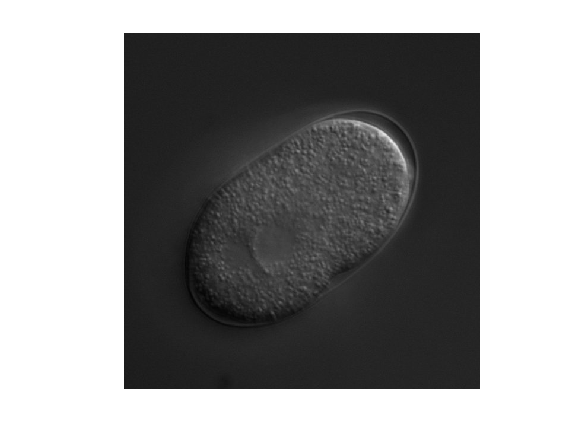

imshow(k_img)

% Accessing quantitative data from the SSBD database
% here we access the data with bdml_ID = 4ed09fa3-7650-45a9-ac55-426980aa7d0a
% ssbd.bd5coords(bdml_id, time, offset, limit)
% 
coords = ssbd.bd5coords("4ed09fa3-7650-45a9-ac55-426980aa7d0a", 0, 0, 20)

bdmlid=4ed09fa3-7650-45a9-ac55-426980aa7d0a, timept=0, offset=0, limit=20
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=4ed09fa3-7650-45a9-ac55-426980aa7d0a&ts=0&offset=0&limit=20



coords = struct with fields:
       meta: [1×1 struct]
    objects: [20×1 struct]


disp(coords.meta)

          limit: 20
           next: '/SSBD/api/v3/bd5coords/?bdmlID=4ed09fa3-7650-45a9-ac55-426980aa7d0a&format=json&limit=20&ts=0&offset=20'
         offset: 0
       previous: []
    total_count: 9691



disp(coords.objects)

  20×1 struct array with fields:

    entity
    id
    label
    radius
    sid
    t
    x
    y
    z



coords.objects.x

ans = '194'

ans = '193'

ans = '193'

ans = '192'

ans = '192'

ans = '192'

ans = '191'

ans = '190'

ans = '189'

ans = '188'

ans = '187'

ans = '186'

ans = '185'

ans = '184'

ans = '183'

ans = '182'

ans = '181'

ans = '180'

ans = '179'

ans = '179'

coords.objects.y

ans = '350'

ans = '351'

ans = '352'

ans = '353'

ans = '354'

ans = '355'

ans = '356'

ans = '356'

ans = '356'

ans = '356'

ans = '356'

ans = '356'

ans = '356'

ans = '356'

ans = '355'

ans = '355'

ans = '355'

ans = '355'

ans = '356'

ans = '357'

coords.objects(2)

ans = struct with fields:
    entity: 'line'
        id: '1000'
     label: 'P0'
    radius: []
       sid: 0
         t: '1'
         x: '193'
         y: '351'
         z: '11'


coords.objects(2).x

ans = '193'

size(coords.objects)

ans =     20     1


scale = ssbd.bd5scaleunit("4ed09fa3-7650-45a9-ac55-426980aa7d0a")

bdmlid=4ed09fa3-7650-45a9-ac55-426980aa7d0a
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5scaleunit/?format=json&bdmlID=4ed09fa3-7650-45a9-ac55-426980aa7d0a&offset=0&limit=1



scale = struct with fields:
       meta: [1×1 struct]
    objects: [1×1 struct]


scale.meta

ans = struct with fields:
          limit: 1
           next: []
         offset: 0
       previous: []
    total_count: 1


scale.objects

ans = struct with fields:
    dimension: '3D+T'
        sUnit: 'micrometer'
       tScale: '40'
        tUnit: 'second'
       xScale: '0.105'
       yScale: '0.105'
       zScale: '0.5'


scale.objects.xScale

ans = '0.105'

## Analysis - plotting proliferation curve of *C. elegans* by counting the number of nucleus

bdmlid = '800faa21-c28c-4b72-bd12-d41f2eed02e8';
limit = 1;
tp = 0;
offset = 0;
limit = 1;
no_of_nucleus = [];
timept = [];
resultdata = ssbd.bd5coords(bdmlid, tp, offset, limit)

bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=0, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=0&offset=0&limit=1



resultdata = struct with fields:
       meta: [1×1 struct]
    objects: [1×1 struct]


disp(["tp=" tp]);

    "tp="    "0"



nn = resultdata.meta.total_count;
while nn > 0
    no_of_nucleus = [no_of_nucleus nn];
    timept = [timept tp];
    tp=tp+1;
    try
        resultdata = ssbd.bd5coords(bdmlid, tp, offset, limit);
        disp(["tp=" tp "nn=" nn]);
        nn = resultdata.meta.total_count;
    catch
        disp("finished")
        nn = -1;
    end
end

bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=1, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=1&offset=0&limit=1



    "tp="    "1"    "nn="    "5"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=2, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=2&offset=0&limit=1



    "tp="    "2"    "nn="    "5"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=3, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=3&offset=0&limit=1



    "tp="    "3"    "nn="    "5"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=4, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=4&offset=0&limit=1



    "tp="    "4"    "nn="    "5"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=5, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=5&offset=0&limit=1



    "tp="    "5"    "nn="    "7"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=6, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=6&offset=0&limit=1



    "tp="    "6"    "nn="    "7"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=7, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=7&offset=0&limit=1



    "tp="    "7"    "nn="    "7"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=8, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=8&offset=0&limit=1



    "tp="    "8"    "nn="    "8"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=9, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=9&offset=0&limit=1



    "tp="    "9"    "nn="    "8"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=10, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=10&offset=0&limit=1



    "tp="    "10"    "nn="    "8"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=11, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=11&offset=0&limit=1



    "tp="    "11"    "nn="    "8"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=12, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=12&offset=0&limit=1



    "tp="    "12"    "nn="    "9"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=13, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=13&offset=0&limit=1



    "tp="    "13"    "nn="    "9"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=14, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=14&offset=0&limit=1



    "tp="    "14"    "nn="    "9"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=15, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=15&offset=0&limit=1



    "tp="    "15"    "nn="    "9"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=16, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=16&offset=0&limit=1



    "tp="    "16"    "nn="    "9"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=17, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=17&offset=0&limit=1



    "tp="    "17"    "nn="    "9"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=18, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=18&offset=0&limit=1



    "tp="    "18"    "nn="    "9"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=19, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=19&offset=0&limit=1



    "tp="    "19"    "nn="    "11"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=20, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=20&offset=0&limit=1



    "tp="    "20"    "nn="    "13"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=21, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=21&offset=0&limit=1



    "tp="    "21"    "nn="    "13"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=22, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=22&offset=0&limit=1



    "tp="    "22"    "nn="    "13"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=23, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=23&offset=0&limit=1



    "tp="    "23"    "nn="    "13"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=24, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=24&offset=0&limit=1



    "tp="    "24"    "nn="    "13"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=25, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=25&offset=0&limit=1



    "tp="    "25"    "nn="    "14"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=26, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=26&offset=0&limit=1



    "tp="    "26"    "nn="    "15"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=27, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=27&offset=0&limit=1



    "tp="    "27"    "nn="    "15"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=28, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=28&offset=0&limit=1



    "tp="    "28"    "nn="    "15"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=29, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=29&offset=0&limit=1



    "tp="    "29"    "nn="    "15"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=30, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=30&offset=0&limit=1



    "tp="    "30"    "nn="    "16"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=31, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=31&offset=0&limit=1



    "tp="    "31"    "nn="    "16"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=32, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=32&offset=0&limit=1



    "tp="    "32"    "nn="    "16"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=33, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=33&offset=0&limit=1



    "tp="    "33"    "nn="    "16"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=34, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=34&offset=0&limit=1



    "tp="    "34"    "nn="    "16"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=35, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=35&offset=0&limit=1



    "tp="    "35"    "nn="    "16"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=36, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=36&offset=0&limit=1



    "tp="    "36"    "nn="    "25"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=37, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=37&offset=0&limit=1



    "tp="    "37"    "nn="    "25"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=38, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=38&offset=0&limit=1



    "tp="    "38"    "nn="    "25"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=39, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=39&offset=0&limit=1



    "tp="    "39"    "nn="    "25"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=40, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=40&offset=0&limit=1



    "tp="    "40"    "nn="    "25"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=41, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=41&offset=0&limit=1



    "tp="    "41"    "nn="    "25"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=42, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=42&offset=0&limit=1



    "tp="    "42"    "nn="    "25"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=43, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=43&offset=0&limit=1



    "tp="    "43"    "nn="    "25"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=44, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=44&offset=0&limit=1



    "tp="    "44"    "nn="    "25"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=45, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=45&offset=0&limit=1



    "tp="    "45"    "nn="    "25"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=46, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=46&offset=0&limit=1



    "tp="    "46"    "nn="    "27"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=47, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=47&offset=0&limit=1



    "tp="    "47"    "nn="    "27"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=48, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=48&offset=0&limit=1



    "tp="    "48"    "nn="    "27"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=49, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=49&offset=0&limit=1



    "tp="    "49"    "nn="    "27"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=50, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=50&offset=0&limit=1



    "tp="    "50"    "nn="    "27"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=51, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=51&offset=0&limit=1



    "tp="    "51"    "nn="    "27"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=52, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=52&offset=0&limit=1



    "tp="    "52"    "nn="    "27"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=53, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=53&offset=0&limit=1



    "tp="    "53"    "nn="    "29"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=54, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=54&offset=0&limit=1



    "tp="    "54"    "nn="    "29"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=55, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=55&offset=0&limit=1



    "tp="    "55"    "nn="    "29"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=56, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=56&offset=0&limit=1



    "tp="    "56"    "nn="    "29"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=57, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=57&offset=0&limit=1



    "tp="    "57"    "nn="    "29"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=58, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=58&offset=0&limit=1



    "tp="    "58"    "nn="    "29"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=59, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=59&offset=0&limit=1



    "tp="    "59"    "nn="    "31"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=60, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=60&offset=0&limit=1



    "tp="    "60"    "nn="    "38"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=61, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=61&offset=0&limit=1



    "tp="    "61"    "nn="    "44"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=62, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=62&offset=0&limit=1



    "tp="    "62"    "nn="    "46"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=63, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=63&offset=0&limit=1



    "tp="    "63"    "nn="    "46"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=64, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=64&offset=0&limit=1



    "tp="    "64"    "nn="    "46"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=65, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=65&offset=0&limit=1



    "tp="    "65"    "nn="    "47"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=66, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=66&offset=0&limit=1



    "tp="    "66"    "nn="    "47"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=67, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=67&offset=0&limit=1



    "tp="    "67"    "nn="    "48"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=68, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=68&offset=0&limit=1



    "tp="    "68"    "nn="    "48"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=69, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=69&offset=0&limit=1



    "tp="    "69"    "nn="    "49"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=70, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=70&offset=0&limit=1



    "tp="    "70"    "nn="    "50"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=71, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=71&offset=0&limit=1



    "tp="    "71"    "nn="    "51"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=72, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=72&offset=0&limit=1



    "tp="    "72"    "nn="    "52"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=73, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=73&offset=0&limit=1



    "tp="    "73"    "nn="    "52"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=74, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=74&offset=0&limit=1



    "tp="    "74"    "nn="    "52"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=75, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=75&offset=0&limit=1



    "tp="    "75"    "nn="    "52"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=76, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=76&offset=0&limit=1



    "tp="    "76"    "nn="    "52"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=77, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=77&offset=0&limit=1



    "tp="    "77"    "nn="    "52"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=78, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=78&offset=0&limit=1



    "tp="    "78"    "nn="    "52"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=79, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=79&offset=0&limit=1



    "tp="    "79"    "nn="    "52"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=80, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=80&offset=0&limit=1



    "tp="    "80"    "nn="    "52"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=81, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=81&offset=0&limit=1



    "tp="    "81"    "nn="    "54"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=82, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=82&offset=0&limit=1



    "tp="    "82"    "nn="    "54"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=83, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=83&offset=0&limit=1



    "tp="    "83"    "nn="    "55"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=84, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=84&offset=0&limit=1



    "tp="    "84"    "nn="    "55"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=85, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=85&offset=0&limit=1



    "tp="    "85"    "nn="    "56"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=86, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=86&offset=0&limit=1



    "tp="    "86"    "nn="    "61"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=87, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=87&offset=0&limit=1



    "tp="    "87"    "nn="    "68"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=88, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=88&offset=0&limit=1



    "tp="    "88"    "nn="    "78"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=89, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=89&offset=0&limit=1



    "tp="    "89"    "nn="    "83"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=90, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=90&offset=0&limit=1



    "tp="    "90"    "nn="    "88"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=91, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=91&offset=0&limit=1



    "tp="    "91"    "nn="    "89"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=92, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=92&offset=0&limit=1



    "tp="    "92"    "nn="    "89"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=93, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=93&offset=0&limit=1



    "tp="    "93"    "nn="    "89"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=94, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=94&offset=0&limit=1



    "tp="    "94"    "nn="    "89"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=95, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=95&offset=0&limit=1



    "tp="    "95"    "nn="    "89"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=96, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=96&offset=0&limit=1



    "tp="    "96"    "nn="    "89"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=97, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=97&offset=0&limit=1



    "tp="    "97"    "nn="    "89"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=98, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=98&offset=0&limit=1



    "tp="    "98"    "nn="    "91"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=99, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=99&offset=0&limit=1



    "tp="    "99"    "nn="    "93"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=100, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=100&offset=0&limit=1



    "tp="    "100"    "nn="    "94"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=101, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=101&offset=0&limit=1



    "tp="    "101"    "nn="    "94"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=102, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=102&offset=0&limit=1



    "tp="    "102"    "nn="    "96"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=103, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=103&offset=0&limit=1



    "tp="    "103"    "nn="    "97"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=104, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=104&offset=0&limit=1



    "tp="    "104"    "nn="    "98"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=105, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=105&offset=0&limit=1



    "tp="    "105"    "nn="    "98"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=106, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=106&offset=0&limit=1



    "tp="    "106"    "nn="    "99"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=107, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=107&offset=0&limit=1



    "tp="    "107"    "nn="    "101"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=108, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=108&offset=0&limit=1



    "tp="    "108"    "nn="    "101"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=109, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=109&offset=0&limit=1



    "tp="    "109"    "nn="    "102"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=110, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=110&offset=0&limit=1



    "tp="    "110"    "nn="    "103"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=111, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=111&offset=0&limit=1



    "tp="    "111"    "nn="    "103"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=112, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=112&offset=0&limit=1



    "tp="    "112"    "nn="    "104"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=113, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=113&offset=0&limit=1



    "tp="    "113"    "nn="    "105"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=114, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=114&offset=0&limit=1



    "tp="    "114"    "nn="    "106"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=115, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=115&offset=0&limit=1



    "tp="    "115"    "nn="    "106"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=116, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=116&offset=0&limit=1



    "tp="    "116"    "nn="    "107"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=117, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=117&offset=0&limit=1



    "tp="    "117"    "nn="    "107"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=118, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=118&offset=0&limit=1



    "tp="    "118"    "nn="    "109"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=119, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=119&offset=0&limit=1



    "tp="    "119"    "nn="    "112"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=120, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=120&offset=0&limit=1



    "tp="    "120"    "nn="    "117"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=121, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=121&offset=0&limit=1



    "tp="    "121"    "nn="    "128"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=122, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=122&offset=0&limit=1



    "tp="    "122"    "nn="    "140"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=123, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=123&offset=0&limit=1



    "tp="    "123"    "nn="    "146"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=124, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=124&offset=0&limit=1



    "tp="    "124"    "nn="    "152"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=125, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=125&offset=0&limit=1



    "tp="    "125"    "nn="    "158"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=126, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=126&offset=0&limit=1



    "tp="    "126"    "nn="    "162"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=127, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=127&offset=0&limit=1



    "tp="    "127"    "nn="    "164"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=128, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=128&offset=0&limit=1



    "tp="    "128"    "nn="    "169"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=129, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=129&offset=0&limit=1



    "tp="    "129"    "nn="    "169"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=130, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=130&offset=0&limit=1



    "tp="    "130"    "nn="    "175"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=131, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=131&offset=0&limit=1



    "tp="    "131"    "nn="    "177"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=132, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=132&offset=0&limit=1



    "tp="    "132"    "nn="    "179"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=133, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=133&offset=0&limit=1



    "tp="    "133"    "nn="    "180"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=134, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=134&offset=0&limit=1



    "tp="    "134"    "nn="    "181"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=135, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=135&offset=0&limit=1



    "tp="    "135"    "nn="    "181"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=136, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=136&offset=0&limit=1



    "tp="    "136"    "nn="    "182"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=137, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=137&offset=0&limit=1



    "tp="    "137"    "nn="    "183"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=138, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=138&offset=0&limit=1



    "tp="    "138"    "nn="    "184"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=139, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=139&offset=0&limit=1



    "tp="    "139"    "nn="    "186"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=140, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=140&offset=0&limit=1



    "tp="    "140"    "nn="    "187"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=141, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=141&offset=0&limit=1



    "tp="    "141"    "nn="    "187"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=142, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=142&offset=0&limit=1



    "tp="    "142"    "nn="    "187"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=143, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=143&offset=0&limit=1



    "tp="    "143"    "nn="    "187"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=144, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=144&offset=0&limit=1



    "tp="    "144"    "nn="    "188"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=145, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=145&offset=0&limit=1



    "tp="    "145"    "nn="    "188"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=146, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=146&offset=0&limit=1



    "tp="    "146"    "nn="    "189"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=147, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=147&offset=0&limit=1



    "tp="    "147"    "nn="    "191"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=148, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=148&offset=0&limit=1



    "tp="    "148"    "nn="    "192"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=149, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=149&offset=0&limit=1



    "tp="    "149"    "nn="    "193"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=150, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=150&offset=0&limit=1



    "tp="    "150"    "nn="    "193"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=151, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=151&offset=0&limit=1



    "tp="    "151"    "nn="    "193"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=152, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=152&offset=0&limit=1



    "tp="    "152"    "nn="    "193"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=153, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=153&offset=0&limit=1



    "tp="    "153"    "nn="    "194"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=154, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=154&offset=0&limit=1



    "tp="    "154"    "nn="    "194"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=155, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=155&offset=0&limit=1



    "tp="    "155"    "nn="    "196"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=156, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=156&offset=0&limit=1



    "tp="    "156"    "nn="    "198"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=157, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=157&offset=0&limit=1



    "tp="    "157"    "nn="    "201"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=158, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=158&offset=0&limit=1



    "tp="    "158"    "nn="    "201"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=159, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=159&offset=0&limit=1



    "tp="    "159"    "nn="    "202"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=160, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=160&offset=0&limit=1



    "tp="    "160"    "nn="    "206"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=161, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=161&offset=0&limit=1



    "tp="    "161"    "nn="    "207"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=162, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=162&offset=0&limit=1



    "tp="    "162"    "nn="    "212"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=163, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=163&offset=0&limit=1



    "tp="    "163"    "nn="    "216"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=164, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=164&offset=0&limit=1



    "tp="    "164"    "nn="    "228"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=165, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=165&offset=0&limit=1



    "tp="    "165"    "nn="    "233"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=166, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=166&offset=0&limit=1



    "tp="    "166"    "nn="    "241"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=167, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=167&offset=0&limit=1



    "tp="    "167"    "nn="    "257"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=168, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=168&offset=0&limit=1



    "tp="    "168"    "nn="    "269"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=169, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=169&offset=0&limit=1



    "tp="    "169"    "nn="    "279"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=170, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=170&offset=0&limit=1



    "tp="    "170"    "nn="    "288"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=171, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=171&offset=0&limit=1



    "tp="    "171"    "nn="    "300"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=172, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=172&offset=0&limit=1



    "tp="    "172"    "nn="    "307"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=173, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=173&offset=0&limit=1



    "tp="    "173"    "nn="    "317"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=174, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=174&offset=0&limit=1



    "tp="    "174"    "nn="    "318"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=175, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=175&offset=0&limit=1



    "tp="    "175"    "nn="    "325"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=176, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=176&offset=0&limit=1



    "tp="    "176"    "nn="    "330"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=177, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=177&offset=0&limit=1



    "tp="    "177"    "nn="    "335"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=178, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=178&offset=0&limit=1



    "tp="    "178"    "nn="    "341"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=179, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=179&offset=0&limit=1



    "tp="    "179"    "nn="    "342"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=180, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=180&offset=0&limit=1



    "tp="    "180"    "nn="    "346"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=181, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=181&offset=0&limit=1



    "tp="    "181"    "nn="    "348"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=182, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=182&offset=0&limit=1



    "tp="    "182"    "nn="    "350"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=183, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=183&offset=0&limit=1



    "tp="    "183"    "nn="    "352"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=184, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=184&offset=0&limit=1



    "tp="    "184"    "nn="    "356"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=185, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=185&offset=0&limit=1



    "tp="    "185"    "nn="    "356"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=186, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=186&offset=0&limit=1



    "tp="    "186"    "nn="    "357"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=187, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=187&offset=0&limit=1



    "tp="    "187"    "nn="    "359"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=188, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=188&offset=0&limit=1



    "tp="    "188"    "nn="    "359"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=189, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=189&offset=0&limit=1



    "tp="    "189"    "nn="    "359"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=190, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=190&offset=0&limit=1



    "tp="    "190"    "nn="    "359"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=191, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=191&offset=0&limit=1



    "tp="    "191"    "nn="    "360"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=192, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=192&offset=0&limit=1



    "tp="    "192"    "nn="    "360"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=193, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=193&offset=0&limit=1



    "tp="    "193"    "nn="    "362"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=194, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=194&offset=0&limit=1



    "tp="    "194"    "nn="    "362"



bdmlid=800faa21-c28c-4b72-bd12-d41f2eed02e8, timept=195, offset=0, limit=1
http://ssbd.qbic.riken.jp/SSBD/api/v3/bd5coords/?format=json&bdmlID=800faa21-c28c-4b72-bd12-d41f2eed02e8&ts=195&offset=0&limit=1



finished


% disp(timept)

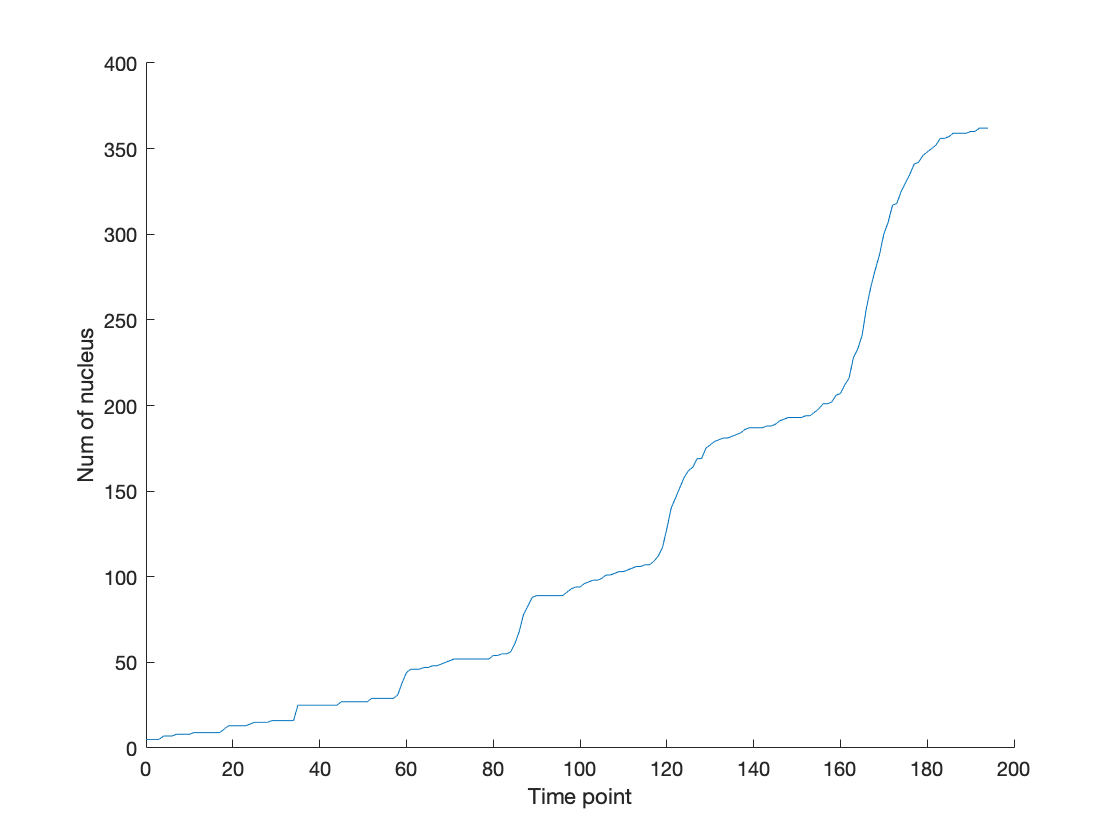

figure;
hold on
plot(timept, no_of_nucleus);
hold off;
xlabel('Time point')
ylabel('Num of nucleus')